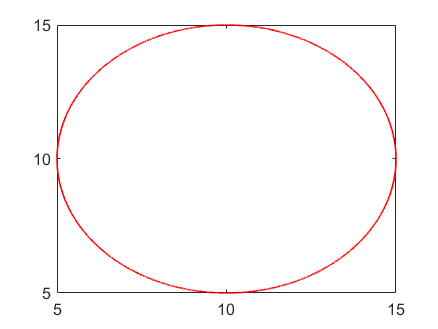

lambda = 5:0.001:15;

s=sqrt(25-(lambda-10).*(lambda-10))+10;
sz=-sqrt(25-(lambda-10).*(lambda-10))+10;
plot(lambda,s,"r","LineWidth",1)
hold on

plot(lambda,sz,"r","LineWidth",1)
hold off

for i=1:50:length(lambda)
m1=acos(sqrt(lambda(i)*lambda(i)+s(i)*s(i))/40);
m2= atan(s(i)/lambda(i));
m=m1+m2;
x1=0:0.01*cos(m):20*cos(m);
y1=0:0.01*sin(m):20*sin(m);
hold on
c1=plot(x1,y1,"r","LineWidth",3);
x2=lambda(i):0.01*cos(pi+m2-m1):lambda(i)+20*cos(pi+m2-m1);
y2=s(i):0.01*sin(pi+m2-m1):s(i)+20*sin(pi+m2-m1);
c2=plot(x2,y2,"r","LineWidth",3);

hold off
pause(0.0000000000001)
delete(c1);
delete(c2);
end
for i=0:50:(length(lambda)-1)
m1=acos(sqrt(lambda(length(lambda)-i)*lambda(length(lambda)-i)+sz(length(lambda)-i)*sz(length(lambda)-i))/40);
m2= atan(sz(length(lambda)-i)/lambda(length(lambda)-i));
m=m1+m2;
x1=0:0.01*cos(m):20*cos(m);
y1=0:0.01*sin(m):20*sin(m);
hold on
c1=plot(x1,y1,"r","LineWidth",3);
x2=lambda(length(lambda)-i):0.01*cos(pi+m2-m1):lambda(length(lambda)-i)+20*cos(pi+m2-m1);
y2=sz(length(lambda)-i):0.01*sin(pi+m2-m1):sz(length(lambda)-i)+20*sin(pi+m2-m1);
c2=plot(x2,y2,"r","LineWidth",3);

hold off
pause(0.0000000000001)
delete(c1);
delete(c2);
end